# Experiment 1

# By Yusuf Ahmed Khan, Serial Number: 12

## Approximation of Square Wave using Fourier Series

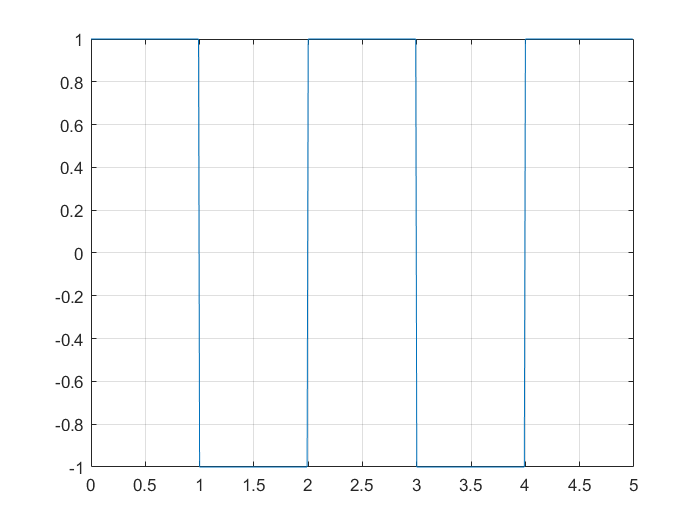

fs=100;
T=2;
w0=2*pi/T;

k=0:1/fs:5-1/fs;
y=square(w0*k, 50);

figure
plot(k,y)
grid on

syms t
N=5;
n=1:N;

a0=(2/T)*(int(1,t,0,1)+int(-1,t,1,2))

$$a0 = 0$$


an=(2/T)*(int(1*cos(n*w0*t),t,0,1)+int(-1*cos(n*w0*t),t,1,2))

$$an = \left(\begin{array}{ccccc} 0 & 0 & 0 & 0 & 0 \end{array}\right)$$


bn=(2/T)*(int(1*sin(n*w0*t),t,0,1)+int(-1*sin(n*w0*t),t,1,2))

$$bn = \left(\begin{array}{ccccc} \frac{4}{\pi } & 0 & \frac{4}{3\,\pi } & 0 & \frac{4}{5\,\pi } \end{array}\right)$$

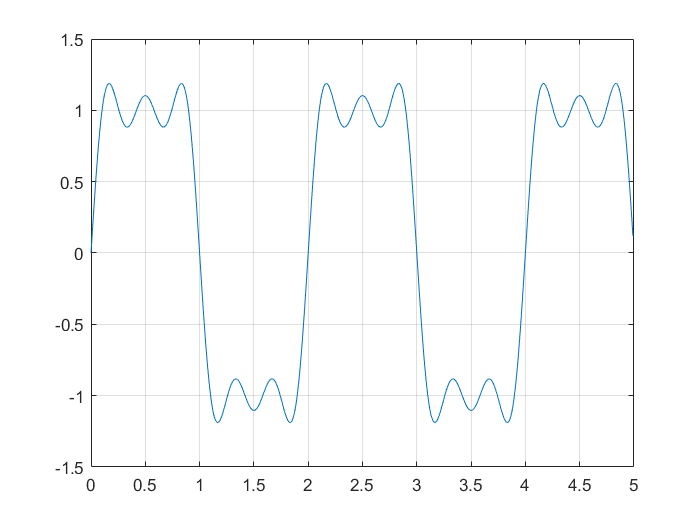

F=a0/2;

for i=1:N
    F=F+an(i)*cos(i*w0*k)+bn(i)*sin(i*w0*k);
    
end


figure
plot(k,F)
grid on

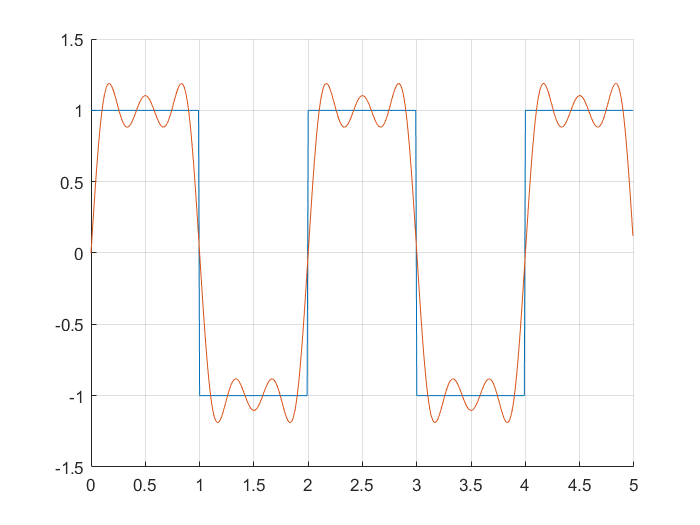

figure
hold on
plot(k,y)
plot(k,F)
hold off
grid on